ts = 2;
plant = ss(0.8,0.5,0.25,0,ts)

plant =
 
  A = 
        x1
   x1  0.8
 
  B = 
        u1
   x1  0.5
 
  C = 
         x1
   y1  0.25
 
  D = 
       u1
   y1   0
 
Sample time: 2 seconds
Discrete-time state-space model.



mpcobj = mpc(plant)

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
 
MPC object (created on 13-May-2023 16:29:10):
---------------------------------------------
Sampling time:      2 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  1 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Distur

mpcobj.MV(1).Min = -2

 
MPC object (created on 13-May-2023 16:29:10):
---------------------------------------------
Sampling time:      2 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  1 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: 0
    ManipulatedVariablesRate: 0.1000
             OutputVariables: 1
                         ECR: 100000

State Estimation:  Default Kalman Filter (type "getEst

mpcobj.MV(1).Max = 2

 
MPC object (created on 13-May-2023 16:29:10):
---------------------------------------------
Sampling time:      2 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  1 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: 0
    ManipulatedVariablesRate: 0.1000
             OutputVariables: 1
                         ECR: 100000

State Estimation:  Default Kalman Filter (type "getEst

xc = mpcstate(mpcobj)

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.
MPCSTATE object with fields
          Plant: 0
    Disturbance: 0
          Noise: [1×0 double]
       LastMove: 0
     Covariance: [2×2 double]



r = 1

r = 1

t = 0:ts:40;
N = length(t);
y = zeros(N,1);
u = zeros(N,1);
for i = 1:N
    y(i) = 0.25*xc.Plant;
    u(i) = mpcmove(mpcobj, xc, y(i), r);
end

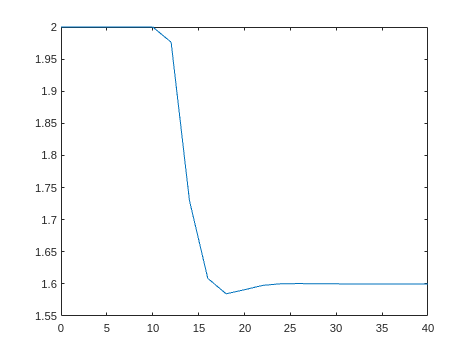

figure()
plot(t,u)

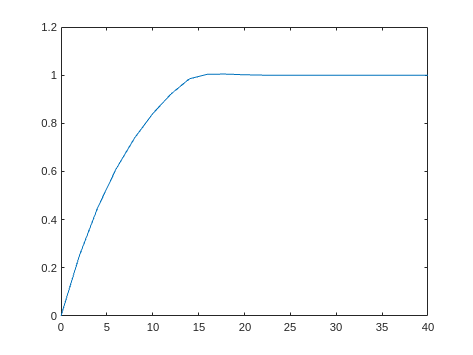

plot(t,y)